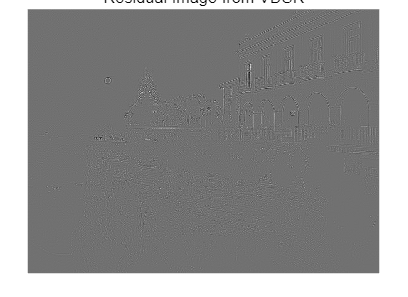

load("trainedVDSRNet.mat");
Iycbcr=imread('B:\360MoveData\Users\15711\Desktop\tempFile\图像处理\test\img\moon.bmp');
Iycbcr=im2double(Iycbcr);
[nrows,ncols,np] = size(Iycbcr);
nrows=2*nrows;
ncols=2*ncols;
Iycbcr = rgb2ycbcr(Iycbcr);
Iy = Iycbcr(:,:,1);
Icb = Iycbcr(:,:,2);
Icr = Iycbcr(:,:,3);
Iy_bicubic = imresize(Iy,[nrows ncols],"bicubic");
Icb_bicubic = imresize(Icb,[nrows ncols],"bicubic");
Icr_bicubic = imresize(Icr,[nrows ncols],"bicubic");
Iresidual = activations(net,Iy_bicubic,41);
Iresidual = double(Iresidual);
imshow(Iresidual,[])
title("Residual Image from VDSR")

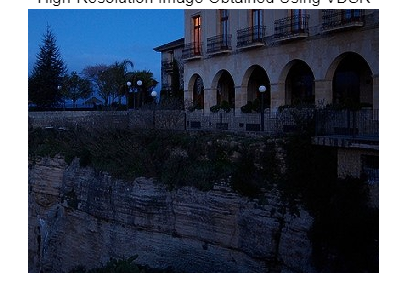

Isr = Iy_bicubic + Iresidual;
Ivdsr = ycbcr2rgb(cat(3,Isr,Icb_bicubic,Icr_bicubic));
imshow(Ivdsr)
title("High-Resolution Image Obtained Using VDSR")

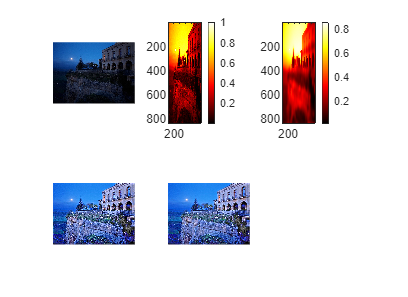

[~,~,I,~]=lime_main_module(Ivdsr,0.01,1.188,5,0.75,1);